clear all

Características da orbita molniya:

    Rotação da linha dos apsides igual a zero.

Inclinação é determinada de modo que a rotação da linha dos apsides seja igual a zero.

i = asind(sqrt(4/5))    %graus

i = 63.4349

Linha dos Apsides mais proxima do polo sul

omega = 270             %graus

omega = 270

Taxa de regressão nodal desejada

Omega_dot_desejado = -360/365.4 %graus/dia

Omega_dot_desejado = -0.9852

Período desejado de meio dia sideral (arbitrário)

T_horas = 12%/1.002738           %horas

T_horas = 12

T_minutos = T_horas * 60        %minutos

T_minutos = 720

T_segundos = T_minutos * 60     %segundos

T_segundos = 43200

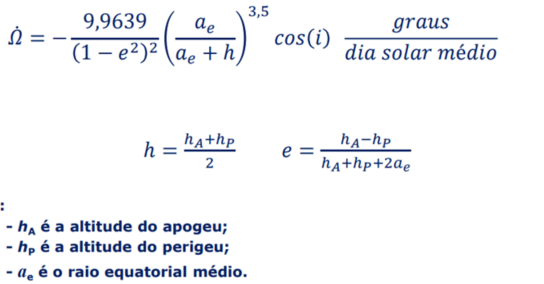

GM = 3.986004418e14 

GM = 3.9860e+14


a = ((T_segundos/2/pi)^2*GM)^(1/3)/1000

a = 2.6610e+04


e = linspace(0,0.92,100)

e =          0    0.0093    0.0186    0.0279    0.0372    0.0465    0.0558    0.0651    0.0743    0.0836    0.0929    0.1022    0.1115    0.1208    0.1301    0.1394    0.1487    0.1580    0.1673    0.1766    0.1859    0.1952    0.2044    0.2137    0.2230    0.2323    0.2416    0.2509    0.2602    0.2695    0.2788    0.2881    0.2974    0.3067    0.3160    0.3253    0.3345    0.3438    0.3531    0.3624    0.3717    0.3810    0.3903    0.3996    0.4089    0.4182    0.4275    0.4368    0.4461    0.4554



regressaoNodal = @(e) Omega_dot(e,a,i) 

regressaoNodal = function_handle with value:
    @(e)Omega_dot(e,a,i)



result = arrayfun(regressaoNodal,e)

result =    -0.0300   -0.0300   -0.0301   -0.0301   -0.0301   -0.0302   -0.0302   -0.0303   -0.0304   -0.0305   -0.0306   -0.0307   -0.0308   -0.0309   -0.0311   -0.0312   -0.0314   -0.0316   -0.0318   -0.0320   -0.0322   -0.0325   -0.0327   -0.0330   -0.0333   -0.0336   -0.0339   -0.0342   -0.0346   -0.0349   -0.0353   -0.0357   -0.0361   -0.0366   -0.0371   -0.0376   -0.0381   -0.0386   -0.0392   -0.0398   -0.0404   -0.0411   -0.0418   -0.0425   -0.0433   -0.0441   -0.0450   -0.0459   -0.0468   -0.0478


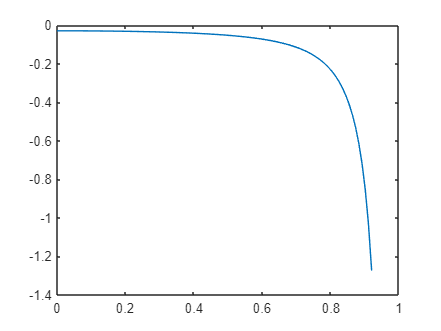


plot(e,result)


e_ideal = fzero(@(e) regressaoNodal(e) - Omega_dot_desejado,0.95)

e_ideal = 0.9085


r_p = a*(1-e_ideal^2)/(1+e_ideal)

r_p = 2.4346e+03

r_a = a*(1-e_ideal^2)/(1-e_ideal)

r_a = 5.0786e+04

a = (r_p+r_a)/2

a = 2.6610e+04


a_e = 6378;      %km
h_a = r_a - a_e

h_a = 4.4408e+04

h_p = r_p - a_e

h_p = -3.9434e+03


T_s = 2*pi*sqrt((a*1000)^3/GM)

T_s = 4.3200e+04

T_m = T_s/60

T_m = 720.0000

T_H = T_m/60

T_H = 12.0000


W_dot_desejado = (24-2*T_H)/24*360

W_dot_desejado = 3.1974e-13

function Om_dot = Omega_dot(e,a,i) 
a_e = 6378;      %km
Om_dot = -9.9639/((1-e^2)^2)*(((a_e)/(a))^3.5)*cosd(i);
end